# Exploring time series with gramm

In this example script, we will explore gramm's capabilities for plotting time series data (or any kind of continous data)

To benefit from interactive elements, you should open it in MATLAB's editor with

We will load a partial dataset from a human movement science experiment

load example_movement.mat
T

T = 3170×15 table
    subject    session    trial_index    reference_direction    hit    m_movement_duration    m_dist    m_reaction_time                 target_pos                  valid_perc    valid_perc_session                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                       

In this dataset, four different subjects (`subject`), came at the lab for two experimental sessions (`session`) on consecutive days . During each of these sessions they learn to control the displacement of a cursor on a screen, and their task is to reach targets with the cursor. The targets are arranged at discrete angles (`reference_direction`) in a circle around a starting point. We record for each movement the cursor trajectories in the horizontal (`px`) and vertical (`py`) dimensions at a sampling rate of 120Hz. Time values in ms from movement onset (`t`) and in percentage of movement completion (`tperc`) are stored. 

**Note here that these time series columns are cells of arrays, in order to store different movement durations for each trial.**

## **Simple time series**

gramm can of course represent simple time series data such as the cursor's horizontal position for a given trial. For these uses it is not much more advantageous compared to standard plotting functions.

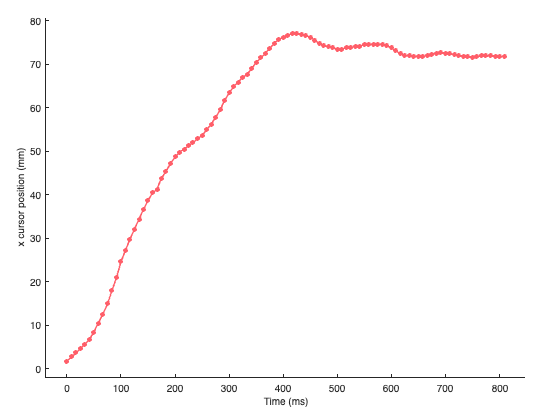

trial = 600;
figure
g=gramm('x',T.t{trial},'y',T.px{trial});
g.geom_line();
g.geom_point();
g.set_names('x','Time (ms)','y','x cursor position (mm)');
g.draw();

## Plotting repeated time series

A big advantage of gramm over equivalent libraries is the ability of gramm to interpret datasets with **repeated time series**. We can plot all horizontal cursor trajectories across the different movement directions with a standard gramm call, despite the movements being of different durations and this having a varying number of samples. `gramm `can use cells of arrays or 2D arrays for this type of data.

**To note:**

- We will plot the various directions in different subplots. Since there are many directions, instead of using `facet_grid()`, we use `facet_wrap()`, which allows a single variable to determine subplot columns, but with wrapping across several rows. This can be deactivated with the button below

- Here we will restrict the display to fast movements of a single subject from the second session, using '`subset'`

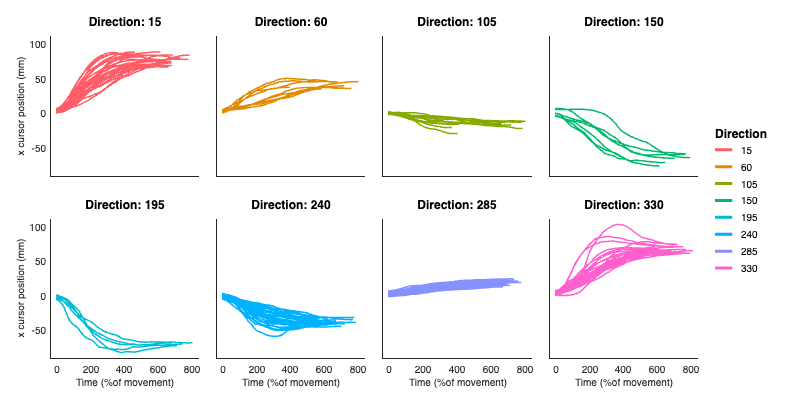

s = true;

figure('Position',[100 100 800 400])
selection = T.subject=="IIFG" & T.session==2 & T.hit==1 & T.m_movement_duration<800;

g=gramm('x',T.t,'y',T.px,'color',T.reference_direction,'subset',selection);
if s
    g.facet_wrap(T.reference_direction);
end
g.geom_line();
g.set_names('x','Time (%of movement)','y','x cursor position (mm)','column','Direction','color','Direction');
g.draw();

### Continuous color scales

As seen above, time series data can be colored using a discrete variable, like the movement direction. When the color aesthetic is mapped to a continuous variable, gramm switches to using a continuous color scale. Here we demonstrate it by coloring movements depending on the progression over both sessions from dark blue to yellow (100% denotes the end of session 1 and 200% the end of session 2). This figure clearly shows the progress of the subject, with shorter and more direct trajectories with learning.

**To note:** the color aesthetic could also be mapped to a variable with the same format as x or y, in which case the color would change within a line.

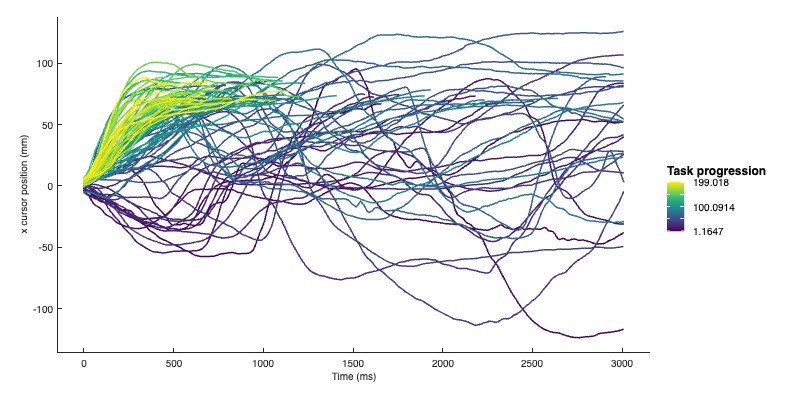

figure('Position',[100 100 800 400])
g=gramm('x',T.t,'y',T.px,'color',T.reference_direction, 'color',T.valid_perc_session,...
    'subset',T.subject=="IIFG" & T.reference_direction==15);
g.geom_line();
g.set_names('x','Time (ms)','y','x cursor position (mm)','Color','Task progression');
g.draw();
%Export
g.export('file_name','timeseries_export','file_type','png');

## Averaging repeated time series

In order to summarize this data, gramm can also average these trajectories, with `stat_summary()`. Here instead of using the column `t` for the x-axis, we use `tperc` which corresponds to a percentage of completion for a given movement.

**Interactive parameters:** Since our timepoints are not aligned, we use linear interpolation on each trajectory with the `'interp_in'` option that will compute the mean and confidence interval at the given number of points along the abcissa.

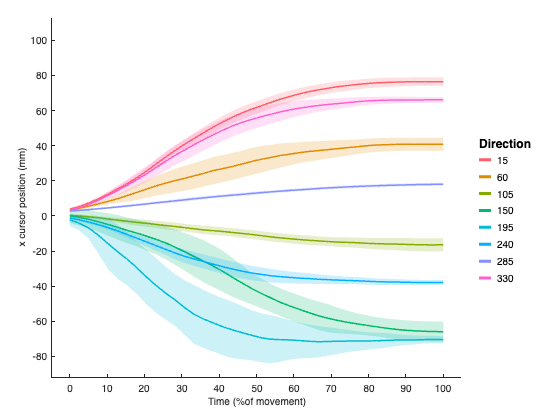

figure
g=gramm('x',T.tperc,'y',T.px,'color',T.reference_direction,'subset',selection);
g.stat_summary('interp_in',40);
g.set_names('x','Time (%of movement)','y','x cursor position (mm)','column','Direction','color','Direction');
g.draw();

## Smoothing time series

If we extract the horizontal velocity of the performed movements  by simple differentiation of the raw data

T.vx = cellfun(@(t,x)[NaN diff(x)./diff(t)],T.t,T.px,'UniformOutput',false);

When displaying the velocities with `geom_line()` we obtain noisy velocity values. If we want to plot smoothed lines we can use `stat_smooth()` instead, which works on repeated trajectories. This is toggled by clicking the button in the code below.

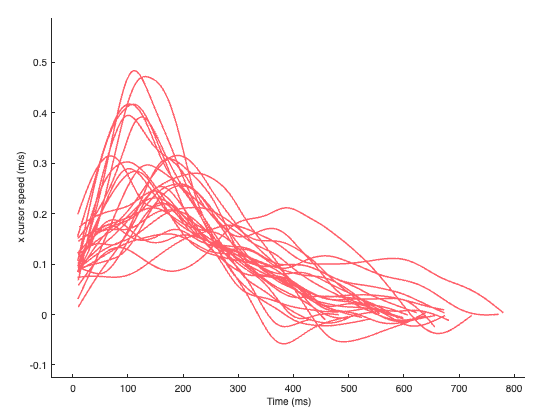

s = true;

figure
g=gramm('x',T.t,'y',T.vx, ...
    'subset',selection & T.reference_direction==15);
if s
    g.stat_smooth();
else
    g.geom_line();
end
g.set_names('x','Time (ms)','y','x cursor speed (m/s)');
g.draw();

## 2D trajectories

Plotting of time series data is not limited to representing one variable against time. We can for example plot the 2D trajectory of the cursor in the plane across all subjects and both sessions. This figure allows us to understand the different movement strategies across subjects, and confirms the vast improvement between experimental sessions.

**To note:**

- Since there are many trajectories in the dataset, we will only plot a fifth of them using `'subset'`

- We need to display trajectories with the correct aspect ratio. Usually this would be done with `axis equal`, which sets the axes property `DataAspectRatio` to [1 1 1]. Since this change needs to be applied to all gramm subplots, we can use the gramm method `axe_property()` to do it all at once.

- We could also provide a `'z'` aesthetic to create 3D plots without further changes

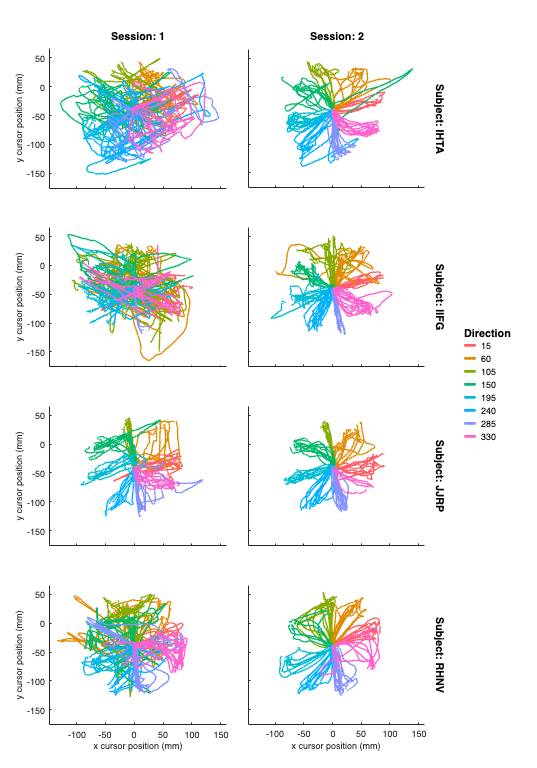

figure('Position',[100 100 700 1000])

g=gramm('x',T.px,'y',T.py,'color',T.reference_direction,'subset',mod(T.trial_index,5)==0);
g.facet_grid(T.subject,T.session);
g.geom_line();
g.set_names('x','x cursor position (mm)','y','y cursor position (mm)','column','Session','color','Direction','row','Subject');
g.axe_property('DataAspectRatio',[1 1 1]);
g.draw();